## HB181 Radar Module Simulations:

This module operates in the X-band, 10.522 GHz to 10.527 GHz.

It is tunable with a 0V - 5V tuning voltage. The slope is -1 MHz / V.

Lets start by simulating FMCW waveforms:

- Say the tuning voltage is swept from 5V to 0V over 1 ms. This will generate an up-chirp of the RF output of the radar.

- The tuning signal will look like this:

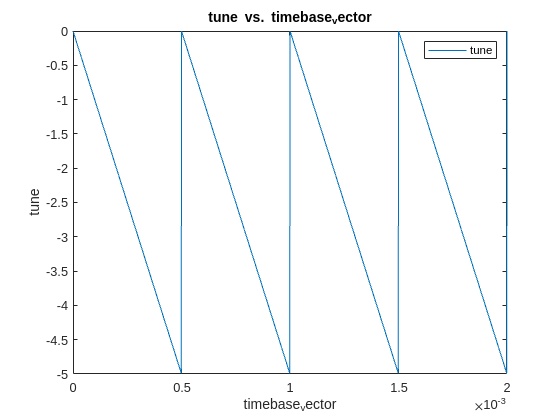

sample_frequency = 1000000;
t_end = 0.002;
period = 0.0005;
timebase_vector = 0:1/sample_frequency:t_end;
tune = -((sawtooth(2*pi*(1/period)*timebase_vector) + 1) / 2) * 5;

% Create plot of timebase_vector and tune
h = plot(timebase_vector,tune,"DisplayName","tune");

% Add xlabel, ylabel, title, and legend
xlabel("timebase_vector")
ylabel("tune")
title("tune vs. timebase_vector")
legend

- The chirp signal will be expressed as follows

%f = (10.527E2 - 1E3 .* tune);
%for i = 1:length(timebase_vector)
%    chirp(i) = sin(2 * pi * f(i) * timebase_vector(i));
%end

chirp = vco(tune, 10E2, 1);

Error using vco
X outside of range [-1,1]


% Create plot of timebase_vector and chirp
h3 = plot(timebase_vector,chirp,"DisplayName","chirp");

% Add xlabel, ylabel, title, and legend
xlabel("timebase_vector")
ylabel("chirp")
title("chirp vs. timebase_vector")
legend

- if the signal propogates and reflects off a surface that is 2 m away the amount of time that the signal is delayed will be found as follows

c = 299792458;
d = 2;
t_prop_delay = 2 * d / c

- the returned signal will look like

chirp_back = circshift(chirp, round(t_prop_delay / (1 / sample_frequency)));

- This returned signal with its time delay will mix with the outgoing signal to give a resulting signal. The difference frequency expresses the range to the target

mixed = chirp .* chirp_back;
information_signal = lowpass(mixed, 0.975E-6);

% Create plot of timebase_vector and information_signal
h2 = plot(timebase_vector,information_signal,"DisplayName","information_signal");

% Add xlabel, ylabel, title, and legend
xlabel("timebase_vector")
ylabel("information_signal")
title("information_signal vs. timebase_vector")
legend